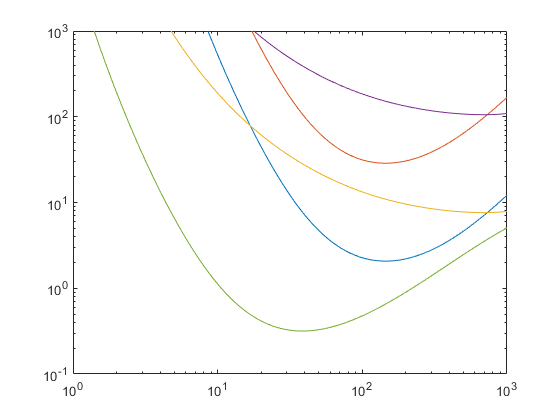

c = 3e10;           % cm/s

files = {
    'D3Hep_ENDF.sv'
    'DDn_ENDF.sv'
    'DTn_ENDF.sv'
    'p11B_ENDF.sv'
};

masses = [2.5, 2, 2.5, 6];          % amu

T = logspace(0, 3, 201);
fs = [0.03 0.30];

figure; hold on; box on;
set(gca, 'XScale', 'log', 'YScale', 'log')
ylim([0.1, 1e3])

for i = 1:length(files)
    
    file = files{i};
    data = dlmread(file);    
    
    sigv = interp1(data(:,1), data(:,2), T);                % cm^3 / s
    cs = c * sqrt(4.*T ./ masses(i) ./ 931.5 ./ 1e3);       % cm / s
    HB = 1.66054e-24 .* 8.*cs.*masses(i)./sigv;
    
    for f = fs
        rhoR = HB .* f ./ (1 - f);
        loglog(T, rhoR)
        hold on;
    end
    
    
end